# An Introduction to MATLAB

by Milind Kumar V

In this live script, you will be introduced to the fundamentals of MATLAB. This will help you get started with the assignment given to you on 9 February 2021. You will be introduced to variables, loops, arrays/vectors and functions among several other concepts. Most of the ideas introduced here are directly relevant to the assignment. 

This live script borrows extensively from Appendix E of Prof. Karthik Raman's book "An Introduction to Computational Systems Biology" which has been shared with you. Further, at different points in this tutorial, you will find numbers enclosed in square brackets (such as [101]) which point you to various sources in the  **References** section at the end of this tutorial which will give you further details of the topic with which the reference is associated.

## Variables

Variables are placeholders which can take on different values. These can be integers and floating point numbers. 

Variables do not need to be declared in MATLAB. For instance, if you wish to create a variable *x *which equals 1, the following statement will suffice

x  = 1

x = 1

The value can be printed (either in the terminal directly or as the output of your (live) script using

disp(x)

     1



MATLAB prints the output of every statement if there is no semi-colon at the end. To avoid this, terminate each statement with a ; as below

y = 1

y = 1

z = 1;

When programming, it is generally a good practice to terminate statements with a semi-colon to avoid printing intermediate values.

## Comments

Comments are lines in the code that are not executed. Using a % at a particular point in the code indicates that you do not wish to execute anything in that line from that point on. This is illustrated below

x = 2; 
% x = 1; This statement is ignored
disp(x);

     2




% x = 2;
% y = 3;
% z = 1e7;

As is evident upon running the above section of code, the value of *x* is set to 2 and the statement setting it to 1 is ignored. Using % allows you to make single line comments. If you wish to make multi-line comments, use %{ ... %} as below

%{
This is a multiline comment

This can be placed at the start of your function to write docstrings or the
like.
%}

## Note: 

For multi-line comments to work, no characters should be placed following the %{ i.e the rest of the line should be left blank.

Comments are extremely useful. You are likely to use them in the following scenarios (in your assignment)-

- To wrtite docstrings- these are strings/comments provided (as documentation) with functions or scripts that help describe the input and output parameters, the algorithm being used, provide details of how the code functions, name the author and elaborate any (perhaps subtle) aspects of the code to enhance the experience of anyone reading the code.

- To comment code- Adding (inline) explanations when writing sophisticated code will make for increased readability.

- When debugging- You might wish to check the functioning of individual modules/functions in your code. You might also wish to isolate certain lines in your code to verfiy their functioning and therefore might comment the rest of the code to prevent its execution.

Refer [1] for more details on effective commenting.

## Operators (refer [2])

Operators are symbols which are used to perform specific computations in MATLAB. While there are several operators, some of the most widely used ones are mentioned below. These are the arithmetic operators.

a = 4 + 2;      % Addition  

Addition: 6


b = 4 - 2;      % Subtraction

Subtraction: 2


c = 4*2;        % Multiplication

Multiplication: 8


d = 4/2;        % Division

Division: 2


e = 4^2;        % Power/exponentiation

Exponentiation: 16



% Printing the results 
disp("Addition: " + string(a));
disp("Subtraction: " + string(b));
disp("Multiplication: " + string(c));
disp("Division: " + string(d));

r: 1


disp("Exponentiation: " + string(e));

Most programming languages (C, Python) use % for the modulo operator. However, MATLAB makes use of the mod() function which is illustrated below

a = 13;         % Dividend
d = 4;          % Divisor
% We wish to obtain the reminder using the modulo operator

Row vector:


r = mod(a,d);   % Reminder, expected value is 1 for a = 13 and d = 4

     1     2     3     4     5



disp("r: " + string(r));        

Column vector:


## Arrays, vectors and matrices (refer [2], [3] and [4])

A vector is a one dimensional array of numbers. Matrices have two dimensions. Higher dimensional structures can also be created using MATLAB. 

### Creation

Vectors (row or column) can be manually defined.

vRow = [1,2,3,4,5];

     1
     2
     3
     4
     5



vColumn = [1; 2; 3; 4; 5];
disp("Row vector:");
disp(vRow);

Row vector


disp("Column vector:");

     1     2     3     4     5     6     7     8     9    10



disp(vColumn);

The colon operator : (refer [4]) is also very useful when generating vectors. If you wish to generate a row vector of numbers from 1 to 10, you could do the following

vRow = 1:10;
disp("Row vector");

     1     3     5     7     9



disp(vRow);

You can also create vectors with numbers increasing or decreasing in steps

% Generate numbers from 1 to 10 in steps of 2
vRow = 1:2:10;

Row vector with upper bound included


disp(vRow);

     0     2     4     6     8    10



**Note: **10 is not included in the output. However, the upper bound when using : is inclusive.

vRowInclusive = 0:2:10;
disp("Row vector with upper bound included");

Vector with numbers in decreasing order


disp(vRowInclusive);

    10     9     8     7     6     5     4     3     2     1



You could also produce numbers in the decreasing order if you wish to.

vRowDecreasing = 10:-1:1;
disp("Vector with numbers in decreasing order");

1-10 with 10 values in between


disp(vRowDecreasing);

     1     2     3     4     5     6     7     8     9    10



Another way to generate vectors is using the linspace or logspace functions. Here, instead of specifying the start value, the end value and the step size, you specify the start value, the end value and the number of points in between. linspace generates linearly separated values whereas logspace generates logarithmically separated values.

**Note: **This will come in handy when you wish to generate X coordinates for plots and you wish to attain greater resolution. See the **Plotting **and **Functions **section.

% Linearly separated values
vRowLinear = linspace(1,10,10);
disp("1-10 with 10 values in between");

1-10 with 5 values placed logarithmically in between


disp(vRowLinear);

    1.0000    1.7783    3.1623    5.6234   10.0000




% Logarithmically separated values
vRowLog = logspace(log10(1),log10(10),5);

Matrix:


disp("1-10 with 5 values placed logarithmically in between");

     1     2     3
     4     5     6
     7     8     9
    10    11    12



disp(vRowLog);

Matrices can be initialised similarly using semicolons.

M = [1,2,3;4,5,6;7,8,9;10,11,12];
disp("Matrix:");

A 3 x 4 matrix of ones: 


disp(M);

     1     1     1     1
     1     1     1     1
     1     1     1     1



While this can be done to generate any sort of matrix, there are easier ways to generate certain "special" matrices.

For instance, a matrix or vector of ones or zeros.

% A 3 x 4 matrix of ones
M1 = ones(3,4);
disp("A 3 x 4 matrix of ones: ");

A 3 x 3 matrix of ones: 


disp(M1);

     1     1     1
     1     1     1
     1     1     1



% A 3 x 3 matrix of ones
M2 = ones(3);
disp("A 3 x 3 matrix of ones: ");

A column vector of ones:


disp(M2);

     1
     1
     1



% A vector of ones
vColumn = ones(3,1);

A row vector of ones:


disp("A column vector of ones:");

     1     1     1



disp(vColumn);
vRow = ones(1,3);
disp("A row vector of ones:");
disp(vRow);


A 3 x 4 matrix of zeros: 


     0     0     0     0
     0     0     0     0
     0     0     0     0



% A 3 x 4 matrix of zeros
M1 = zeros(3,4);
disp("A 3 x 4 matrix of zeros: ");

A 3 x 3 matrix of zeros: 


disp(M1);

     0     0     0
     0     0     0
     0     0     0



% A 3 x 3 matrix of zeros
M2 = zeros(3);
disp("A 3 x 3 matrix of zeros: ");

A column vector of zeros:


disp(M2);

     0
     0
     0



% A vector of zeros
vColumn = zeros(3,1);

A row vector of zeros:


disp("A column vector of zeros:");

     0     0     0



disp(vColumn);
vRow = zeros(1,3);
disp("A row vector of zeros:");
disp(vRow);

3 x 3 identity matrix


An n x n identity matrix can be generated using the eye() function

% Generating a 3 x 3 identity matrix

     1     0     0
     0     1     0
     0     0     1



M = eye(3);
disp("3 x 3 identity matrix");
disp(M);

### Accessing elements from vectors and matrices 

v = 1:2:20;
M = [1,2,3;4,5,6;7,8,9;10,11,12];

Vector v:


disp("Vector v:");

     1     3     5     7     9    11    13    15    17    19



disp(v);

Matrix M:


disp("Matrix M:");

     1     2     3
     4     5     6
     7     8     9
    10    11    12



disp(M);

**Elements are indexed from 1** and can be accessed using (). Therefore to access the 3rd element of *v* 

thirdElement = v(3);
disp("The third element of v:");

The third element of v:


disp(thirdElement);

     5



To access the element in the second row and third column of `M``,`

matrixElement = M(2,3);
disp("The element in the 2nd row and 3rd column of M");

The element in the 2nd row and 3rd column of M


disp(matrixElement);

     6



Vectors/Matrices can also be **sliced** to obtain subsets of elements as follows

% Extracting every 3rd element from v
vSlice = v(1:3:end);
disp("Every 3rd element from v");

Every 3rd element from v


disp(vSlice);

     1     7    13    19




% Extracting some elements of M
MSlice = M(2:end, 2:end);
disp("A block of M");

A block of M


disp(MSlice);

     5     6
     8     9
    11    12



Further, the number of elements in or the shape of a vector/matrix can be determined using length and size.

lengthV = length(v);
disp("length of v: " + string(lengthV));

length of v: 10


sizeM = size(M);
disp("shape of M: " + string(sizeM(1)) + " x " + string(sizeM(2)));

shape of M: 4 x 3


### Operators

Operations on vectors and matrices with constants are supported in MATLAB. They are illustrated below

disp("Vector v:");

Vector v:


disp(v);

     1     3     5     7     9    11    13    15    17    19



disp("Matrix M:");

Matrix M:


disp(M);

     1     2     3
     4     5     6
     7     8     9
    10    11    12




% Adding a constant
v1 = v + 3;
disp("Adding a constant to v");

Adding a constant to v


disp(v1);

     4     6     8    10    12    14    16    18    20    22



M1 = M + 3;
disp("Adding a constant to M");

Adding a constant to M


disp(M1);

     4     5     6
     7     8     9
    10    11    12
    13    14    15



Similarly constants can be subtracted from, multiplied with and can divide vectors and matrices. MATLAB also supports other elementwise operations. This is for 2 or more vectors of the same size.

disp("Vector 1:");

Vector 1:


disp(v);

     1     3     5     7     9    11    13    15    17    19



v1 = linspace(2,20,10);
disp("Vector 2:");

Vector 2:


disp(v1);

     2     4     6     8    10    12    14    16    18    20




% Addition
disp("Adding the two vectors");

Adding the two vectors


disp(v + v1);

     3     7    11    15    19    23    27    31    35    39



% Subtraction
disp("Subtracting the two vectors");

Subtracting the two vectors


disp(v - v1);

    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1



% Multiplication
disp("Multiplying the vectors elementwise");

Multiplying the vectors elementwise


disp(v.*v1);

     2    12    30    56    90   132   182   240   306   380



% Divsion
disp("Dividing the two vectors elementwise");

Dividing the two vectors elementwise


disp(v./v1);

    0.5000    0.7500    0.8333    0.8750    0.9000    0.9167    0.9286    0.9375    0.9444    0.9500



% Exponentiation
disp("Elementwise exponentiation");

Elementwise exponentiation


disp(v.^v1);

   1.0e+25 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0014    3.7590



These operations are similar for Matrices. However, Matrix multiplication is different and uses the * operator. Two matrices can be multiplied if they have the following shapes- m x r and r x n which results in a m x n matrix. Below, M and transpose(M) are multiplied. The transpose is obtained using the ' operator.

% M x M'
disp("transpose(M)");

transpose(M)


disp(M')

     1     4     7    10
     2     5     8    11
     3     6     9    12



disp("Multiplying M and M': ");

Multiplying M and M': 


disp(M*M');

    14    32    50    68
    32    77   122   167
    50   122   194   266
    68   167   266   365



### reshape and repmat

Matrices and vectors can be reshaped using the repmat and reshape functions. Transforming vectors to matrices and vice versa is a useful operation- one that is often performed when using FFT/IFFT and the like. This is illustrated below

disp("Reshaping v into a 2 x 5 matrix");

Reshaping v into a 2 x 5 matrix


vMatrix = reshape(v,[2,5]);
disp(vMatrix);

     1     5     9    13    17
     3     7    11    15    19



 Note that this has been done column first. This can also be done row first. 

disp("Reshaping so that the first elements are in the first row");

Reshaping so that the first elements are in the first row


vMatrix = reshape(v,[],2)';
disp(vMatrix);

     1     3     5     7     9
    11    13    15    17    19



Using [] as one of the arguments allows MATLAB to calculate the dimensaion length on its own. This can be done for matrices as well. 

Using *repmat* allows one to create larger matrices using a matrix as a block. This is shown below.

disp("Original matrix");

Original matrix


disp(M);

     1     2     3
     4     5     6
     7     8     9
    10    11    12



MRepeated = repmat(M, 3, 2);
disp("Larger matrix");

Larger matrix


disp(MRepeated);

     1     2     3     1     2     3
     4     5     6     4     5     6
     7     8     9     7     8     9
    10    11    12    10    11    12
     1     2     3     1     2     3
     4     5     6     4     5     6
     7     8     9     7     8     9
    10    11    12    10    11    12
     1     2     3     1     2     3
     4     5     6     4     5     6
     7     8     9     7     8     9
    10    11    12    10    11    12



## Random numbers (refer [5])

There are multiple functions to generate random numbers in MATLAB. Primarily, you will either have to generate uniformly distributed random numbers or normally distributed random numbers. 

### Uniformly distributed random numbers

This can be done using the *rand *[6] and *randi *[7] functions. Generating random numbers according to the uniform distribution is very useful. For instance, consider the problem where you wish to randomly generate bits with each bit being 0 or 1 with equal likelihood. The following is one way to do this

% rand returns a value between 0 and 1
a = rand;
if (a < 0.5)
    bit = 0;
else
    bit = 1;
end
disp("Generated bit: " + string(bit));

Generated bit: 1


The value *bit* is likely to be either 0 or 1 with a likelihood of 0.5. Another way to do this is using the *randi* function. 

% Generating one bit using randi
numBits = 1;
bit = randi([0,1],numBits);
disp("Generated bit: " + string(bit));

Generated bit: 1


If you want to generate a sequence of numbers, then set *numBits *equal to the length of the sequence. 

### Gaussian random numbers

Generating numbers that are distributed according to a normal distribution is often necessary. You can do this using the *randn *[8] function. This generates a number distributed according to N(0,1). This is illustrated below

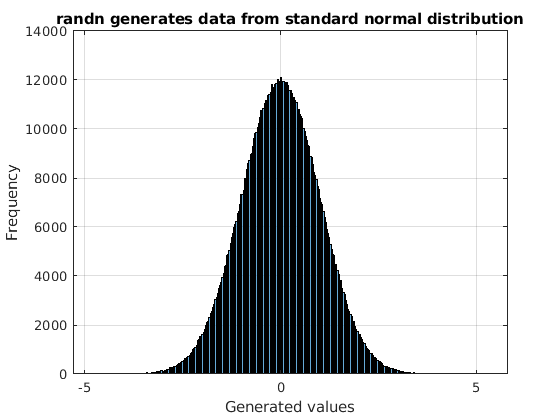

% Generate a large number of numbers distributed according to the standard
% normal distribution
numValues = 1e6;
stdValues = randn(numValues,1);

% Visualise the values
histogram(stdValues);
title("randn generates data from standard normal distribution");
xlabel("Generated values");
ylabel("Frequency");
grid on


disp("Mean: " + string(mean(stdValues)));

Mean: 0.0027704


disp("Variance: " + string(var(stdValues)));

Variance: 1.0014


In many circumstances (such as when simulating an AWGN channel), it might be necessary to generate data from a Normal distribution with a different mean and variance. This can be done as follows

y = (sigma)*X + mu

where 

- sigma = desired standard deviation

- X ~ N(0,1)

- mu = desired mean

If you wish to obtain random numbers distributed as N(2,3) i.e from a normal distribution with mean 2 and variance 3 (standard deviation sqrt(3)), you could do the following

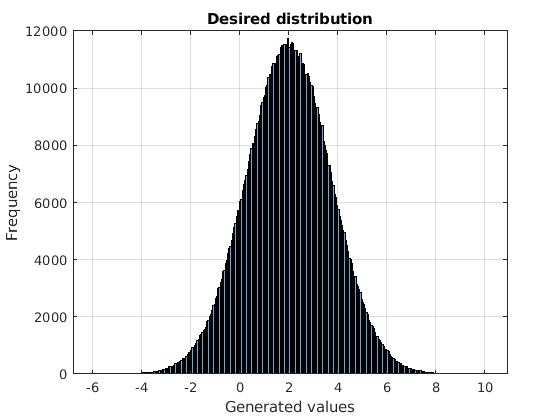

meanVal = 2;
sigmaVal = sqrt(3);
values = sigmaVal*randn(numValues,1) + meanVal;

% Visualise the values
histogram(values);
title("Desired distribution");
xlabel("Generated values");
ylabel("Frequency");
grid on


disp("Mean: " + string(mean(values)));

Mean: 2.0006


disp("Variance: " + string(var(values)));

Variance: 2.997


**Note: **If you want to produce repeatable results, make sure to set the seed of the random number generator.

## Conditional statements (refer [2], [9])

You will find if, else and elseif statements used below. However, in order to perform complicated operations with these statements, it is essential to understand relational and logical oeprators. Relational operators are presented below. 

a = 3;
b = 4;

disp("Equal: " + string(a == b));

Equal: false


disp("Not equal: " + string(a ~= b));

Not equal: true


disp("Greater than or equal to: " + string(a >= b));

Greater than or equal to: false


disp("Greater than: " + string(a > b));

Greater than: false


disp("Less than or equal to: " + string(a <= b));

Less than or equal to: true


disp("Less than: " + string(a < b));

Less than: true


Logical operators are useful when describing complex conditions which need to be fulfilled in order to execute a particular piece of code. They are presented below.

a = true;
b = false;

disp("a: " + string(a));

a: true


disp("b: " + string(b));

b: false


disp("NOT a: " + string(~a));

NOT a: false


disp("a AND b: " + string(a&b));

a AND b: false


disp("a OR b: " + string(a|b));

a OR b: true


The if statement [9] can be used to determine which block of code to execute at runtime. This is illustrated below

a = false;
b = false;

if (b)
    disp("b is true");
elseif (a)
    disp("a is true");
else 
    disp("Neither is true");
end

Neither is true


You can also use the *switch-case *statement in some circumstances. Refer [9] for more details.

## Loops (refer [10])

Loops help you execute a block of code over and over again. The *for *and *while *loops are what you will likely be using. Simple examples are given below

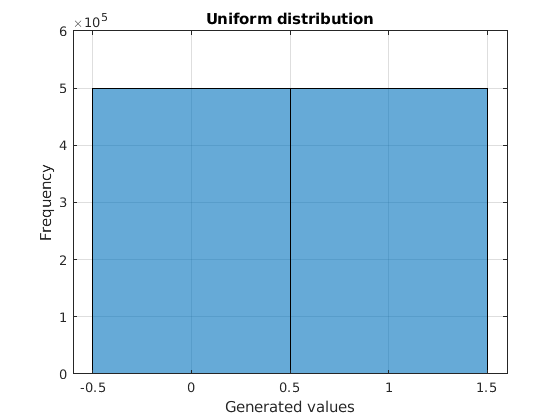

% Using a for loop to generate a bits from a uniform distribution
bits = [];
numBits = 1e6;

for i = 1:numBits
    val = rand;
    if (rand < 0.5)
        bits(i) = 0;
    else 
        bits(i) = 1;
    end
end

% Visualise the values
histogram(bits);
title("Uniform distribution");
xlabel("Generated values");
ylabel("Frequency");
grid on

Refer [10] for the syntax of *while *loops which can be used in a similar fashion.

## Plotting

Plotting is an absolutely essential part of any scientific work. **People pay attention to plots! **Therefore, you must ensure the folllowing when preparing and presenting a plot-

- It must have a title

- Both the axes must be labelled (and have units mentioned if necessary)

- There must be a grid

- There must be a legend whenever appropriate

MATLAB allows for some fantastic plotting using functions such as *plot, semilogy, semilogx *and so forth. Below, the use of *semilogy* is demonstrated. Refer the MATLAB documentation for the remaining functions. Below, we will attempt to generate the theoretical BER vs Eb/N0 curves for 4, 16, 64, 256 QAM. This is a part of your assignment as well. For this, the *generateCurve* function has been used. Details of how to write functions are given in the **Functions **section of this tutorial.

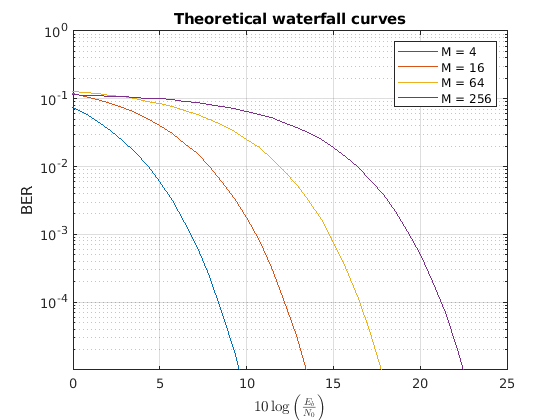

% Generate all four curves
y = [];     % Final array of BER values
x = [];     % Final array of Eb/N0 values
mList = []; % Array of constellation values
n = 50;     % Number of points in each curve


for m = 1:4
    M = 2^(2*m);
    mList(i) = M;
    [Y,X] = generateCurve(M,n);
    y = [y; Y];
    x = [x; X];
end


% Plotting
figure
semilogy(x',y');
ylim([1e-5,1]);
xlim([0,25]);
grid on
xlabel("$10\log\left(\frac{E_b}{N_0}\right)$", "Interpreter", "latex");
ylabel("BER");
title("Theoretical waterfall curves");
legend("M = 4", "M = 16", "M = 64", "M = 256")

The theoretical plot is based on several assumptions. Refer the "Signal processing and detection" chapter by John M. Cioffi (already shared with you) to get a better understanding of what is going on. Above, it is assumed that the constellations are gray encoded i.e adjacent constellation points only differ in a single bit.

## Functions

Functions can be used to isolate blocks of code that need to be run repeatedly. This increases the modularity of your code. Functions can have both inputs and outputs. For every function you write, ensure that

- Associated documentation is present

- The function name is appropriate

- Function is at the end of the file

%{
Function to generate the theoretical BER vs SNR curves for an AWGN channel 

Author: Milind Kumar V

[Y,X] = generateCurve(M)

Inputs: 
    M (int): constellation used
    n (int): number of points desired in the plot
Outputs:
    Y (array): BER values corresponding to the values in X. Same size
        as X.
    X (array): values of Eb/N0 for which the BER is computed for the given
        constellation
%}


function [Y,X] = generateCurve(M,n)
    X = linspace(-10, 25, n);
    x = X/10;
    x = 10.^x;
    % Referr Signal Processing and Detection by John M. Cioffi
    Y = qfunc(sqrt(3*log2(M)/(M-1)*x));;
    Y = 4*(1 - 1/sqrt(M))*Y;
    Y = Y - Y.^2/4;
    Y = Y/log2(M); 
end

When writing complicated code, you might want to write your functions in different .m files and then include their paths in the primary script. This will increase the modularity and readability of your code.

## Further learning

Some things you might wish to learn about are

- Data types in MATLAB

- Splitting a line of code over multiple lines using ...

- Advanced plotting 

- Functions such as *qammod *which can be used to generate the required constellation points

## Documentation

MATLAB provides extensive documentation for almost all its functions. Make sure to refer to the documentation online to understand the behaviour of different functions in MATLAB. Further, you can access this documentation by using the *help *command in the Command Window. Typing 

help <function_name>

will give you some details about the function and point you to more detailed documentation. This can also be done using *doc.*

doc <function_name>

when used as a command in the command window will take you to more detailed documentation.    

## References

[1] [https://www.cs.utah.edu/~germain/PPS/Topics/commenting.html](https://www.cs.utah.edu/~germain/PPS/Topics/commenting.html) 

[2] [https://in.mathworks.com/help/matlab/matlab_prog/matlab-operators-and-special-characters.html](https://in.mathworks.com/help/matlab/matlab_prog/matlab-operators-and-special-characters.html) 

[3] "An Introduction to Computational Systems Biology" by Karthik Raman (CRC Press, 2021; ISBN:  9781138597327)

[4] [https://in.mathworks.com/help/matlab/ref/colon.html](https://in.mathworks.com/help/matlab/ref/colon.html) 

[5] [https://in.mathworks.com/help/matlab/random-number-generation.html](https://in.mathworks.com/help/matlab/random-number-generation.html) 

[6] [https://in.mathworks.com/help/matlab/ref/rand.html](https://in.mathworks.com/help/matlab/ref/rand.html) 

[7] [https://in.mathworks.com/help/matlab/ref/randi.html](https://in.mathworks.com/help/matlab/ref/randi.html)  

[8] [https://in.mathworks.com/help/matlab/ref/randn.html](https://in.mathworks.com/help/matlab/ref/randn.html) 

[9] [https://in.mathworks.com/help/matlab/matlab_prog/conditional-statements.html](https://in.mathworks.com/help/matlab/matlab_prog/conditional-statements.html) 

[10] [https://in.mathworks.com/help/matlab/matlab_prog/loop-control-statements.html](https://in.mathworks.com/help/matlab/matlab_prog/loop-control-statements.html)  